This example shows DIDO control of a distillation column.  The example is from [https://www.mathworks.com/help/control/ug/build-a-model-of-a-multi-input-multi-output-mimo-control-system.html](https://www.mathworks.com/help/control/ug/build-a-model-of-a-multi-input-multi-output-mimo-control-system.html) 

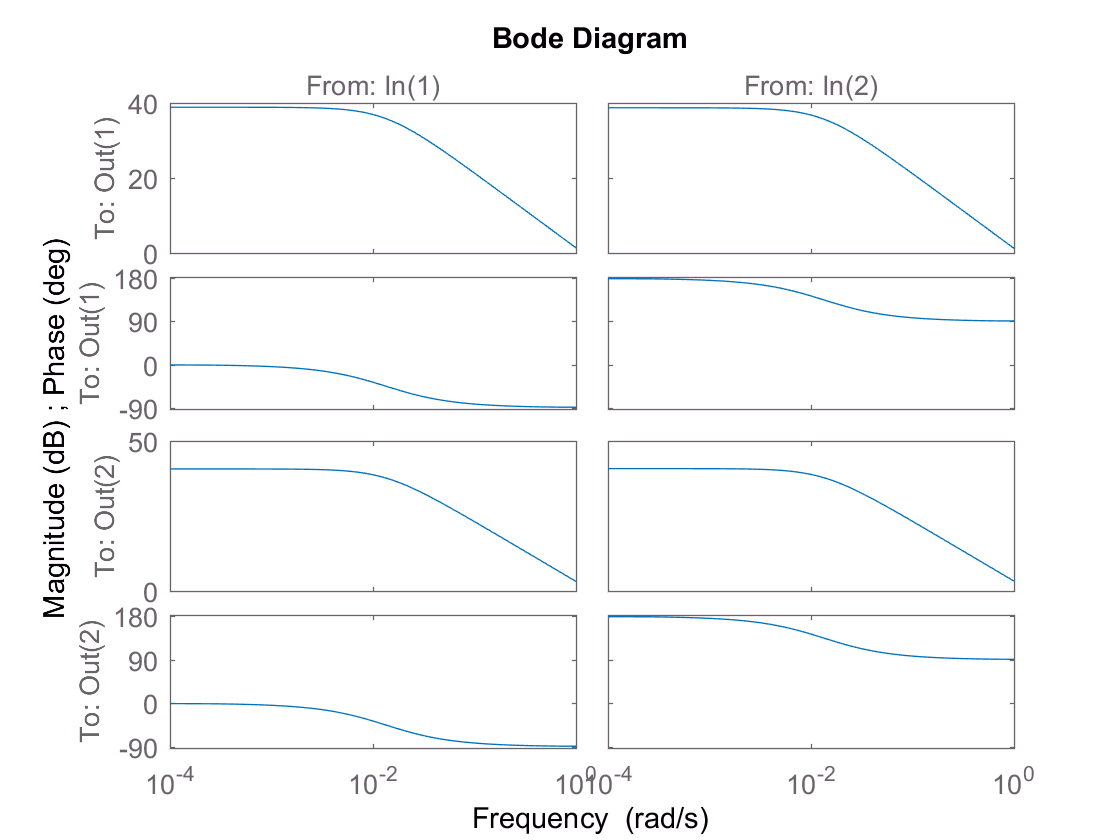

s = tf('s');
G = 1/(75*s+1)*[87.8 -86.4;108.2 -109.6];
bode(G)

SISO Assumption

The system shows very strong interaction, but let's try a diagonal controller anyway for starters.  I'll design for a very simple loopshape $L_i(s) = \frac{10}{s}$.  Below the additional poles at $s=-100$ exist to make the controller realizable.

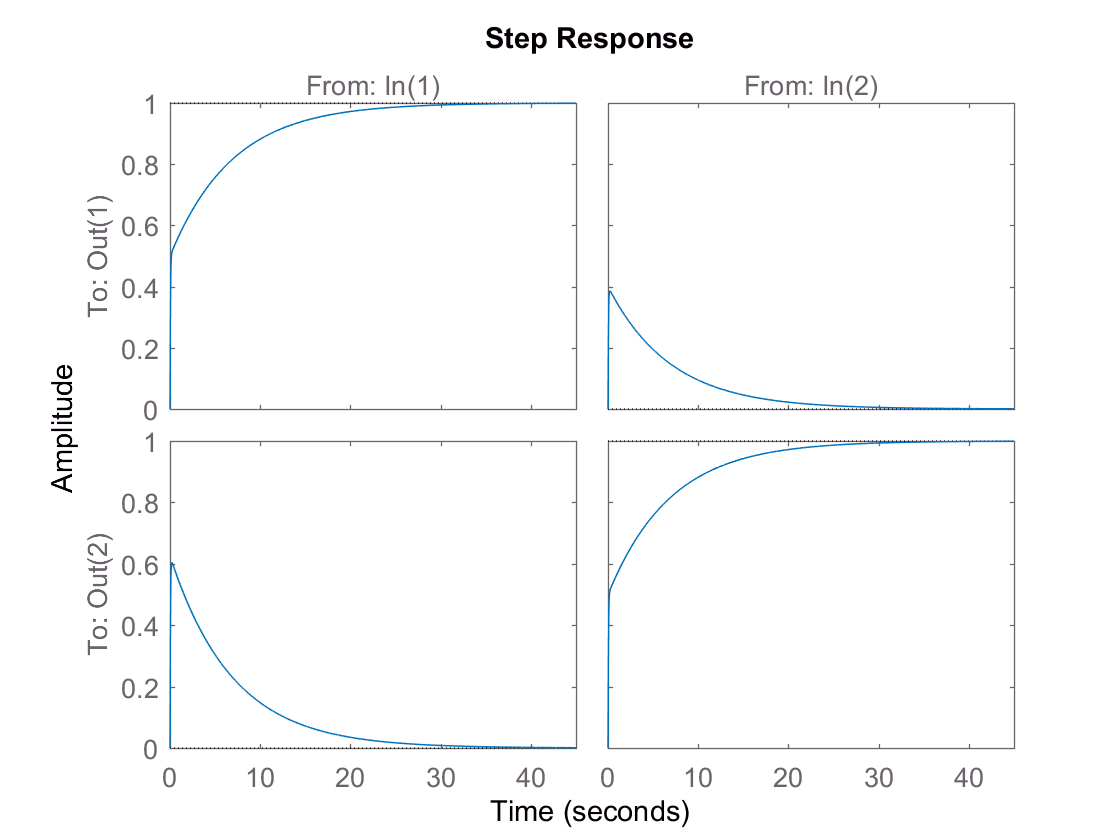

K11 = inv(G(1,1))*10/s/(s+100);
[mag,phase] = bode(G(1,1)*K11,10);
K11 = K11/mag;
K22 = inv(G(2,2))*10/s/(s+100);
[mag,phase] = bode(G(2,2)*K22,10);
K22 = K22/mag;
K_siso = [K11 0;0 K22];
L_siso = G*K_siso;
T_siso = feedback(L_siso,eye(2));
S_siso = eye(2)-T_siso;
step(T_siso)

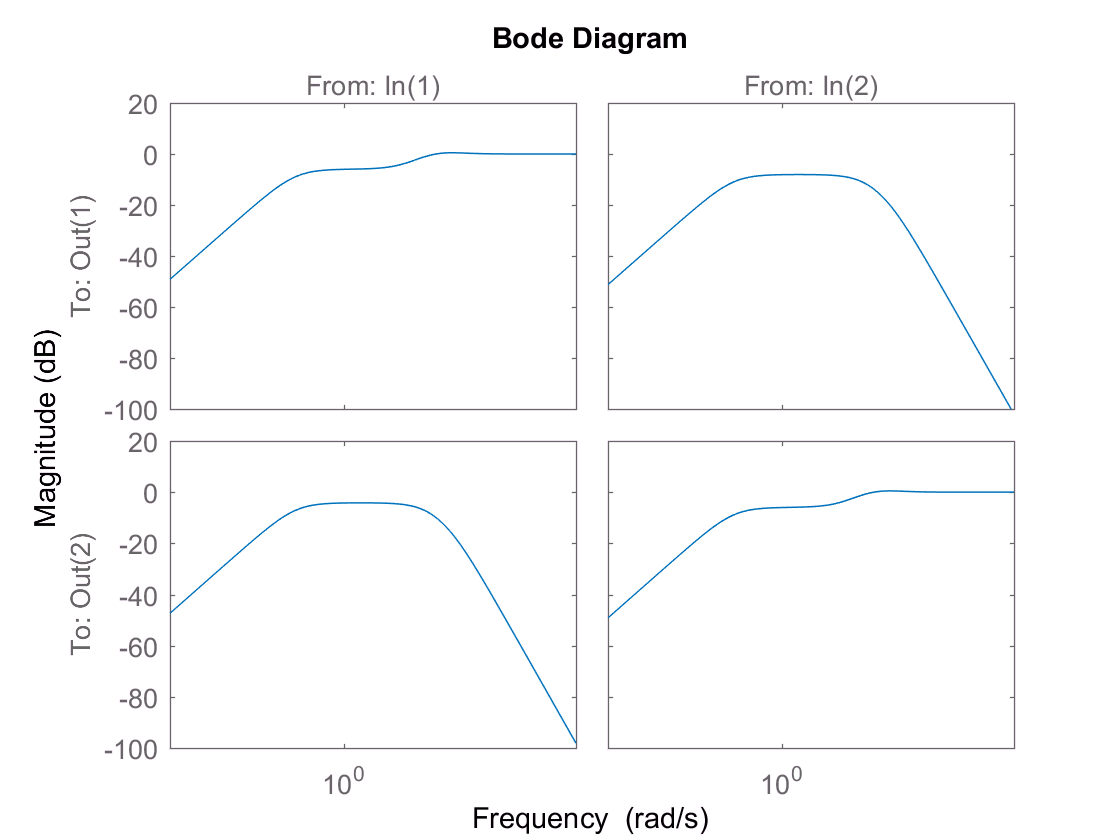

bodemag(S_siso)

It works, and for the step input it effectively achieves steady state rejection of the interactions.  But we can do better.

Dynamic Decoupling

Now design a precompensator.  Because $G^{-1}$ is improper we need to multiply by higher order poles again.

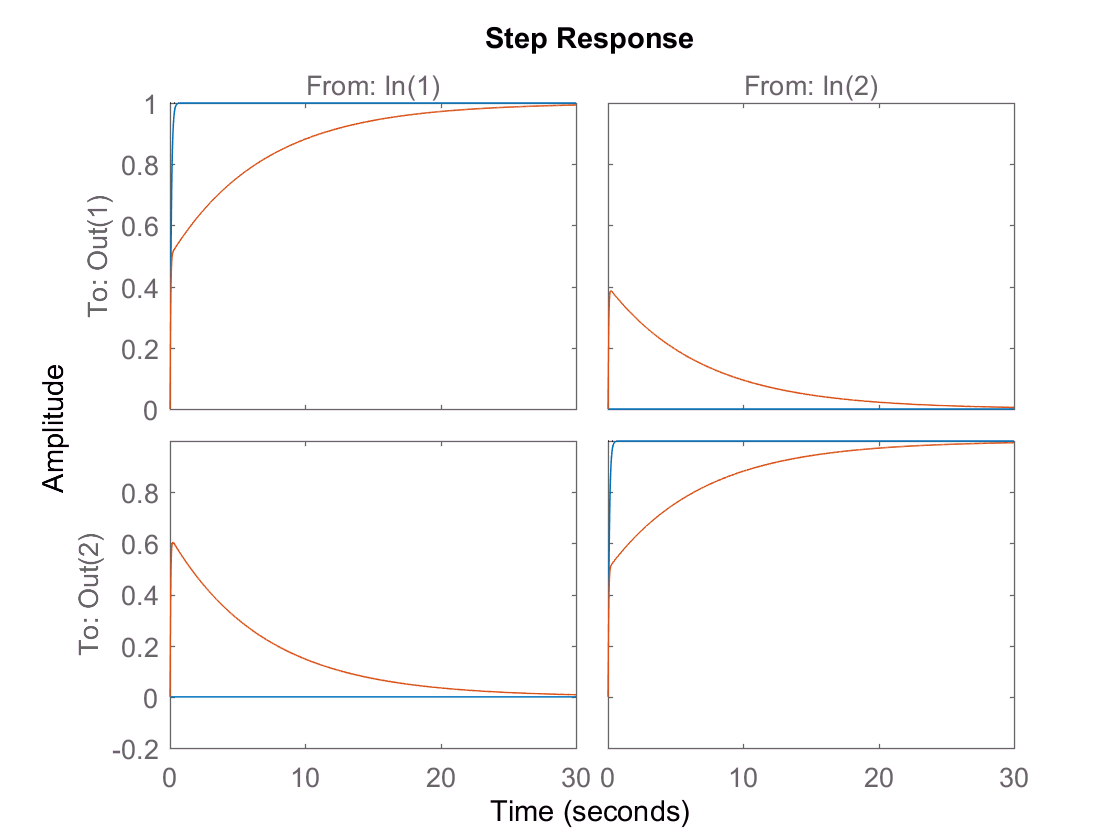

Ginv = inv(G)*100/(s+100)*eye(2);
K_inv = Ginv*[10/s 0;0 10/s];
L_inv = G*K_inv;
T_inv = feedback(L_inv,eye(2));
S_inv = eye(2)-T_inv;
step(T_inv,T_siso,30)

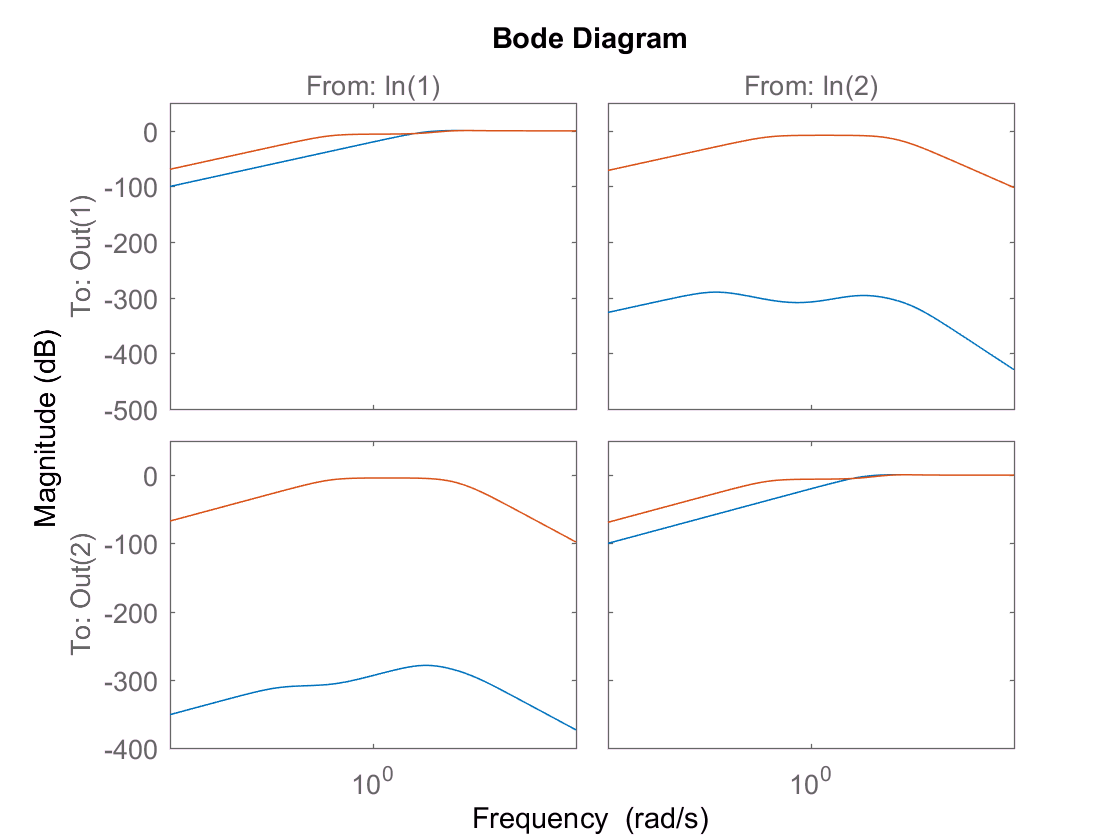

bodemag(S_inv,S_siso)

The performance for the dynamic decoupling design is drastically better than the performance for the SISO assumption, as should be the case.  We have stopped ignoring the interactions and actively compensate for them.

SVD Controller

Here we use an SVD controller, assuming that we want to decouple the system at zero.  I don't expect this to be better than the dynamic decoupler, but it's easier to use, especially for non-square systems.

[U,Sig,V] = svd([87.8 -86.4;108.2 -109.6]);
W1 = V;
W2 = U';

We performed the static decoupling at 0.  Now, to deal with the pole at 1/75, we introduce a zero in the loopshape to cancel.

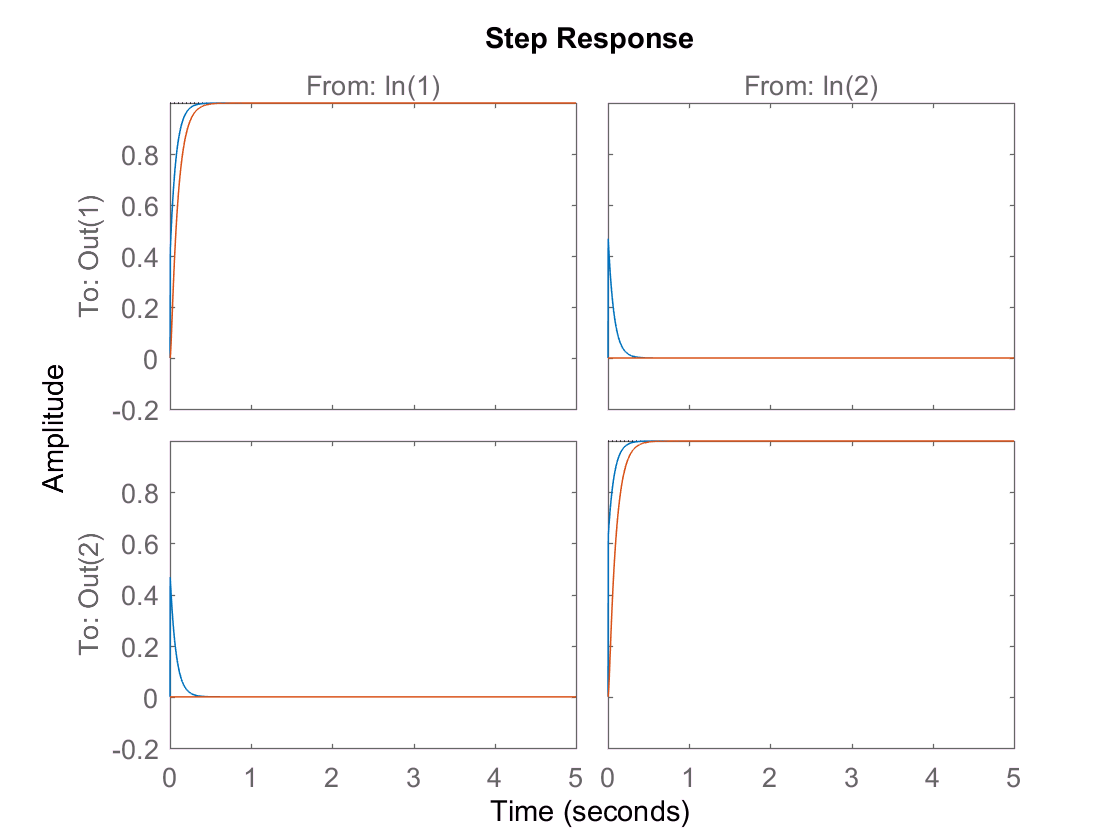

K_svd = W1*[10*(75*s+1)/s 0;0 10*(75*s+1)/s]*W2;  %Cancel the plant pole
L_svd = G*K_svd;
T_svd = feedback(L_svd,eye(2));
S_svd = eye(2)-T_svd;
step(T_svd,T_inv,5)

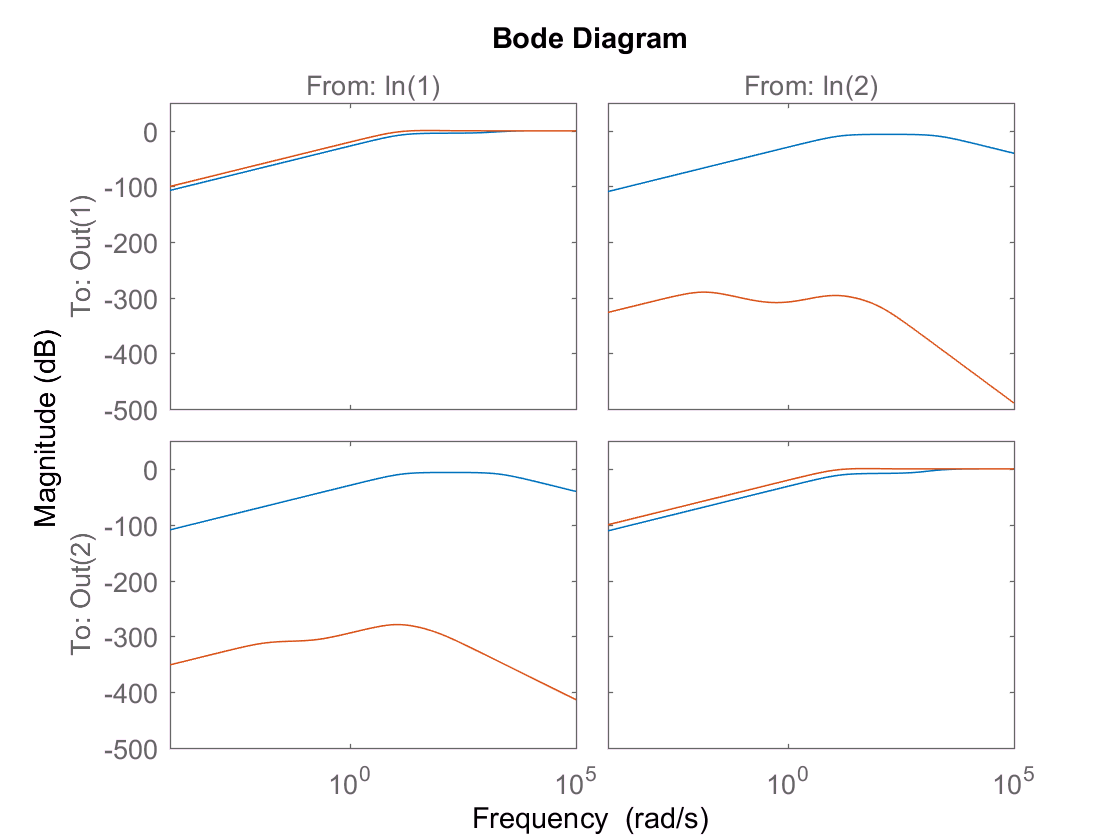

bodemag(S_svd,S_inv)

The dynamic decoupler has much better decoupling performance, but the SVD controller performs well in the time domain